% 아래와 같은 분포를 갖는 독립적인 n개의 random variables의 합으로 
% 새로운 r.v.을 생성하여 central limit theorem 확인 (새로운 r.v.의 개수= 10^7)
% Uniform Distribution (0 ≤ x ≤ 1)
% (a) n = 3      (b) n = 6      (c) n = 12      (d) n = 20
% 0부터 1사이에서 uniform distribution을 갖는 n개의 r.v.들의 합으로 새로운 r.v.을 생성한다.

## n = 3

sgtitle('after standard')
arr1 = zeros(1,10^7);
for cnt = 1:3
    for i = 1:10^7
        arr1(i) = arr1(i) + rand();
    end
end

m1 = mean(arr1); v1 = var(arr1);
std1 = (arr1-m1).*(1/sqrt(v1))

std1 =     0.7011   -0.6474   -0.3860   -0.5771    0.4895    1.1431    0.6102   -0.3677   -0.3795   -1.5706    0.6717   -0.3716   -0.4748   -1.9666   -0.1527    0.4903   -0.5091    0.2384    1.7163   -1.1989   -0.2201    0.6689   -0.4372    0.4187   -0.7945   -0.0839    0.9176    0.4650    0.3092   -0.2575    0.8589   -0.6092    1.2749    0.0692    0.0103   -1.6129    0.9955   -0.5746    1.0276   -0.8747   -0.0080   -1.3597   -0.3970    0.3712   -0.8370    0.5120   -0.6301   -0.1791   -1.8851   -0.5230


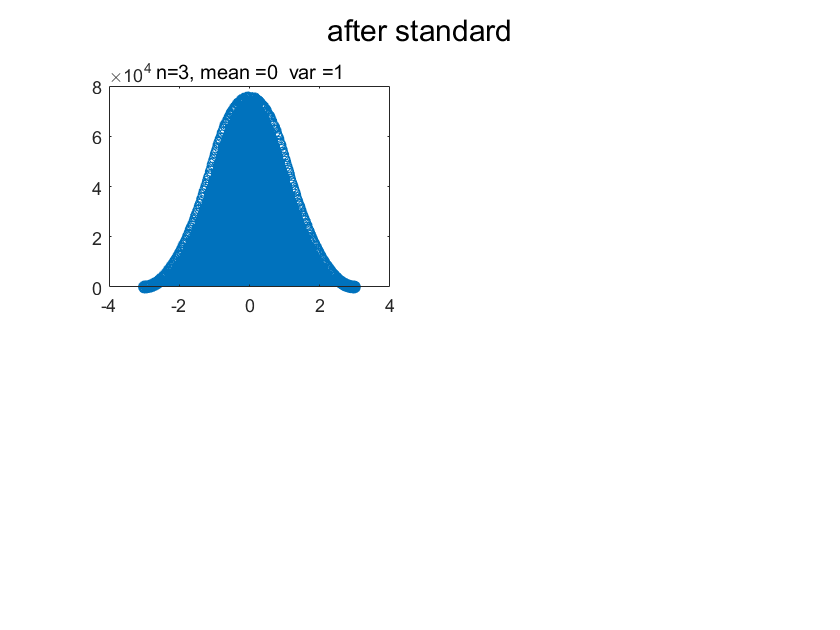

m1 = round(mean(std1),2); v1 = round(var(std1),2);
[N1,~] = histcounts(std1);
subplot(2,2,1)
stem(linspace(min(std1),max(std1),length(N1)),N1)
title(['n=3, mean =',num2str(m1),'  var =',num2str(v1)])

% histogram(arr1) <- matlab doesn't recommand it

## n = 6

arr2 = zeros(1,10^7);
for cnt = 1:6
    for i = 1:10^7
        arr2(i) = arr2(i) + rand();
    end
end

m2 = mean(arr2); v2 = var(arr2);
std2 = (arr2 - m2).*(1/sqrt(v2))

std2 =     2.0712   -1.1369   -0.2775   -0.0937   -0.4396   -0.1810    1.3625    1.2706    0.7936   -0.9024    0.3719   -1.3420    1.4937   -2.6418   -1.6938    0.9885   -0.1227    1.3377   -0.0681   -0.6524   -2.4165   -1.3609    0.7769    0.2927    0.3167   -1.8288   -0.8902   -0.5225    1.7346   -0.1590   -1.5302    0.5583   -2.4021   -2.6679    0.6016   -0.4074    0.4253   -0.5382    0.9351    2.5068    0.2752    0.0231   -0.7665    0.2537    0.6880   -1.3948   -1.1570   -1.4618    0.6405    0.0656


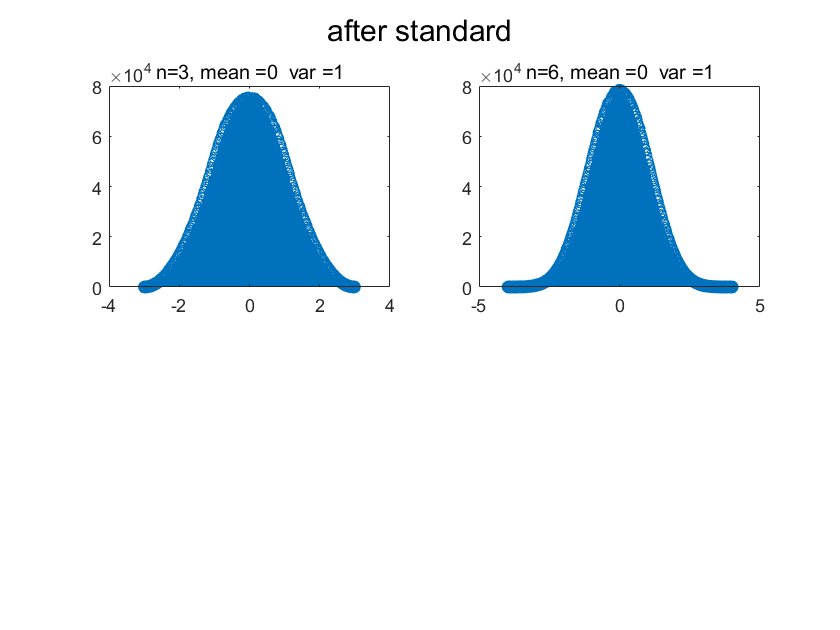

m2 = round(mean(std2),2); v2 = round(var(std2),2);
[N2,~] = histcounts(std2);
subplot(2,2,2)
stem(linspace(min(std2),max(std2),length(N2)),N2)
title(['n=6, mean =',num2str(m2),'  var =',num2str(v2)])

## n = 12

arr3 = zeros(1,10^7);
for cnt = 1:12
    for i = 1:10^7
        arr3(i) = arr3(i) + rand();
    end
end
m3 = mean(arr3); v3 = var(arr3);
std3 = (arr3 - m3).*(1/sqrt(v3))

std3 =     0.1571   -1.4687   -0.3429   -1.3449    1.3121   -0.1185    1.0172    1.0676   -1.3720   -0.5172   -1.9909    0.5686    1.8584   -0.1762   -1.0747   -0.0241   -0.0558    0.0448   -1.4196    0.1982   -0.1519   -0.8412    0.0501    2.3375    0.6811   -1.2787    0.6204    0.4387   -0.0855   -0.9760    0.9214   -0.0976   -0.2383    0.7373   -0.5695    0.9043    0.8598   -0.0270    1.3753   -0.9462   -1.6354    0.3948    1.3434    1.7441    1.7204    0.9928    1.1587   -0.5030    0.0196    0.2375


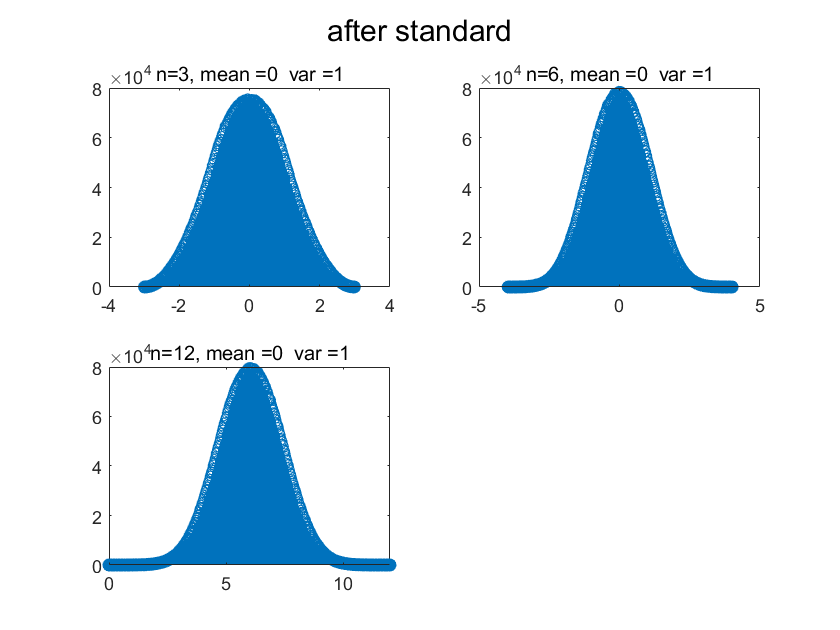

m3 = round(mean(std3),2); v3 = round(var(std3),2);
[N3,~] = histcounts(std3);
subplot(2,2,3)
stem(linspace(0,12,length(N3)),N3)
title(['n=12, mean =',num2str(m3),'  var =',num2str(v3)])
xlim([0,12])

## n = 20

arr4 = zeros(1,10^7);
for cnt = 1:20
    for i = 1:10^7
        arr4(i) = arr4(i) + rand();
    end
end
m4 = mean(arr4); v4 = var(arr4);
std4 = (arr4 - m4).*(1/sqrt(v4))

std4 =    -1.0259   -0.1269   -1.0788   -0.5467    0.2951   -1.4355   -1.7468    0.8461   -1.2675    0.3932    0.3764    0.0781    1.1017    0.7393    1.1834    1.0700   -0.6562    1.3136    0.8956   -0.7379   -0.7218   -1.1615   -1.0905   -0.7088   -0.7039    1.6183    0.9472   -2.7723   -0.6293   -0.7265   -0.8921   -1.0593   -1.0645    0.4609   -0.6724   -0.2033    0.5579   -0.3078    1.4905    1.2929   -0.3372    0.2030   -0.3208   -0.3461   -0.7114    0.0034   -1.0877    0.2829    0.2577   -0.0215


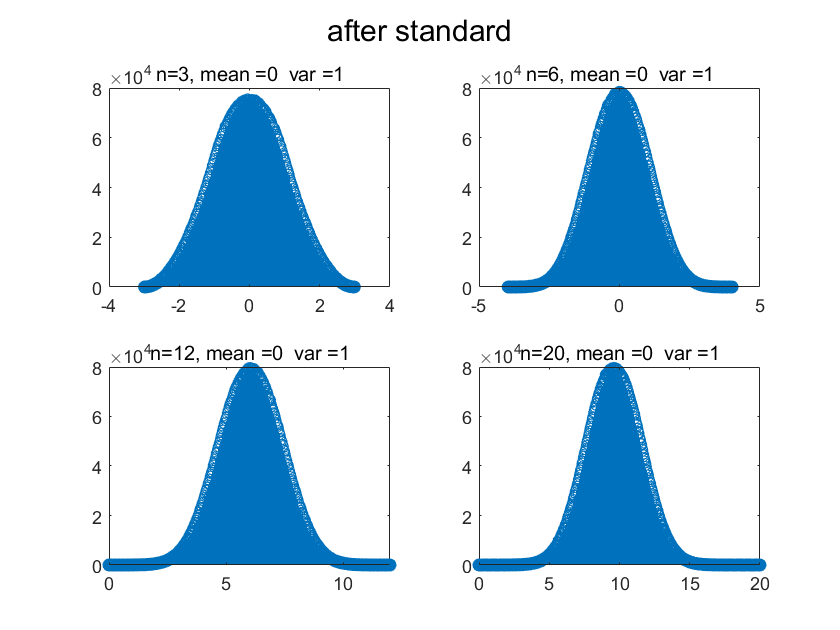

m4 = round(mean(std4),2); v4 = round(var(std4),2);
[N4,~] = histcounts(std4);
subplot(2,2,4)
stem(linspace(0,20,length(N4)),N4)
title(['n=20, mean =',num2str(m4),'  var =',num2str(v4)])